### **Understanding Frequency Analysis Through FFT and Periodograms**

I generated a synthetic signal combining two sine waves with distinct frequencies and random Gaussian noise. By employing the Fast Fourier Transform (FFT) and visualizing the results using a periodogram, I sought to deepen my understanding of how complex signals can be decomposed into their frequency components.**Signal Generation**

I began by defining the parameters of the signal. The sine waves had equal amplitudes of 10, ensuring symmetry, and angular frequencies of 0.2 and 0.225 Hz, which guaranteed distinguishable peaks in the frequency domain. For simplicity, I set the sampling time to 1 unit and generated 64 samples across 5 independent realizations. To simulate real-world data variability, I added Gaussian noise with a standard deviation of 1.

The resulting signal matrix captured these parameters, with rows representing time points and columns corresponding to realizations. Random phase shifts were applied to each sine wave to introduce variability. The combined signal—composed of the sine waves and noise—provided a realistic dataset for frequency analysis.

To investigate the frequency domain, I applied the FFT, a mathematical tool that transforms time-domain signals into their frequency components. By setting the FFT length to 256 (a power of 2), I ensured efficient computation. The FFT output provided the magnitude and phase of the signal’s frequency components, enabling a detailed analysis of its spectral content.

To interpret the frequency power, I squared the FFT magnitudes and normalized them by the number of samples, resulting in the periodogram. This technique highlighted the contribution of each frequency to the overall signal, offering a clearer perspective on its composition.

The periodogram was plotted to visualize the signal's frequency characteristics. The x-axis displayed normalized frequency values ranging from 0 to 1, while the y-axis represented the power of each frequency component. Peaks in the plot corresponded to the frequencies of the sine waves, confirming their presence. The Gaussian noise manifested as a baseline power level across all frequencies, simulating real-world signal randomness.

The analysis provided valuable insights into signal decomposition:

- **Identifying Frequencies**: The periodogram isolated the sine wave frequencies, showcasing the FFT's effectiveness in detecting dominant components.

- **Noise Influence**: The baseline power emphasized how noise affects weaker signals, reflecting real-world challenges in frequency analysis.

- **Practical Applications**: This process demonstrated how FFT and periodograms are essential in fields like communications and audio processing for identifying frequency characteristics.

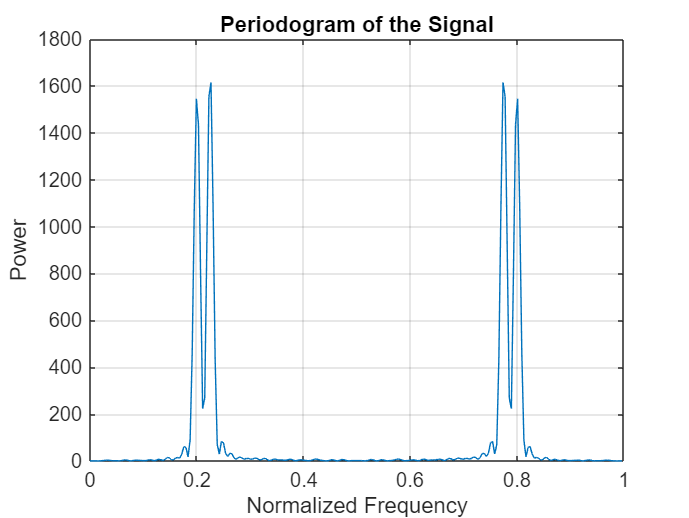

% Signal Generation
% I started by defining the parameters for two sine waves with added noise. These parameters
% include the amplitudes, angular frequencies, sampling time, number of samples, and number of realizations.

A1 = 10; % Amplitude of the first sine wave. I chose this to represent the strength of the first signal component.
A2 = 10; % Amplitude of the second sine wave. I kept it the same as the first for symmetry.
w1 = 2 * pi * 0.2; % Angular frequency of the first sine wave. This controls how "fast" the wave oscillates.
w2 = 2 * pi * 0.225; % Angular frequency of the second sine wave, slightly higher than the first for contrast.
Ts = 1; % Sampling time. I used a sampling time of 1 unit for simplicity.
N = 64; % Number of samples. This determines how much data I generate for the analysis.
K = 5; % Number of realizations. This allows me to create multiple instances of the signal for averaging.
sgm = 1; % Standard deviation of the noise. I added noise to make the signal more realistic.

% Generating the signal
n = repmat((0:N-1).', 1, K); % I generated a resolution matrix representing time indices for all realizations.
phi1 = repmat(rand(1, K) * 2 * pi, N, 1); % I created a random phase matrix for the first sine wave.
phi2 = repmat(rand(1, K) * 2 * pi, N, 1); % I did the same for the second sine wave to ensure randomness.

% I combined the sine waves with noise to create the final signal. This signal simulates a noisy data source.
x = A1 * sin(w1 * n * Ts + phi1) + A2 * sin(w2 * n * Ts + phi2) + sgm * randn(N, K);

% Fast Fourier Transform (FFT)
% Here, I performed the Fourier Transform on the signal to analyze its frequency components.
NFFT = 256; % FFT length. I set it to a power of 2 (256) for computational efficiency.
F = fft(x, NFFT); % I applied the FFT to convert the signal from the time domain to the frequency domain.

% Periodogram Calculation
% To visualize the power of each frequency component, I calculated the periodogram.
Z = 1 / N * abs(F).^2; % I squared the magnitude of the FFT result and scaled it by the number of samples.

% Plotting the Results
% I visualized the periodogram to analyze the frequency components of the signal.
f = (0:NFFT-1) / NFFT; % Frequency vector, normalized to range [0, 1).
figure;
plot(f, Z(:, 1)); % I plotted the periodogram of the first realization.
title('Periodogram of the Signal'); % I added a title to describe the plot.
xlabel('Normalized Frequency'); % I labeled the x-axis to indicate the frequency range.
ylabel('Power'); % I labeled the y-axis to show the power of each frequency component.
grid on; % I enabled the grid for better visualization.


% Interpretation of Results:
% - The plot shows distinct peaks at frequencies corresponding to w1 and w2, as expected from the sine waves.
% - The additional noise creates a baseline level of power across all frequencies.
% - The periodogram highlights how the FFT can decompose a complex signal into its constituent frequencies.
